# Transformación Invariante PCA

## ¿Qué es?

El método basado en PCA (Análisis de Componentes Principales) propuesto por Kim genera un espacio invariante a la iluminación que permite reducir el efecto de sombras y variaciones en la intensidad de la luz. El algoritmo busca la proyección óptima en el espacio logarítmico-cromático para minimizar la variabilidad causada por la iluminación.

## Funcionamiento básico de la transformación

**1. Modelo espectral RGB:**

La respuesta espectral de un canal específico $\rho_k$ (con 𝑘={𝑟,𝑔,𝑏}) se define como:


$$\rho_k = \sigma \int E(\lambda) S(\lambda) Q_k(\lambda) d\lambda$$


donde:

- $\sigma$: factor constante que denota el sombreado de Lambert.

- $E(\lambda)$: iluminación incidente en el elemento de superficie percibida.

- $S(\lambda)$: reflectancia espectral de la superficie.

- $Q(\lambda)$: sensibilidad espectral del canal $k$.

- $\lambda$: longitud de onda.

**2. Transformación logarítmica:**

El algoritmo convierte el modelo a un espacio logarítmico para minimizar el efecto de la iluminación. Se calculan las siguientes relaciones logarítmicas:


$$r = \log \frac{R}{(RGB)^{1/3}}, \quad b = \log \frac{B}{(RGB)^{1/3}}
$$


donde:

- $(RGB)^{1/3}$: media geométrica de los tres canales.

**3. Proyección basada en PCA:**

Se proyectan los valores en un espacio logarítmico-cromático, donde se encuentra la dirección óptima utilizando PCA:


$$I_{\theta} = r \cos \theta + b \sin \theta
$$


Esto se logra aplicando el Análisis de Componentes Principales a los valores calculados.

## Análisis de la implementación:

**1. Parámetros de entrada:**

- $image$: imagen en formato RGB.

**2. Ajuste de la imagen para evitar logaritmos negativos:**

Añadir 1 a todos los píxeles para evitar valores negativos en los cálculos logarítmicos.

image = image + 1;

**3. Muestreo aleatorio de píxeles:**

Se toma una muestra aleatoria del 1% de los píxeles para calcular la dirección de proyección.

[h, w, ~] = size(image);
sample_size = ceil(h * w / 100);
sampled_pixels = zeros(3, sample_size);

% Muestreo aleatorio de píxeles
for z = 1:sample_size
    x = randi(w);   y = randi(h);
    sampled_pixels(:, z) = reshape(image(y, x, :), [3 1]);
end

img_R = sampled_pixels(1, :);
img_G = sampled_pixels(2, :);
img_B = sampled_pixels(3, :);

geoM = (img_R .* img_G .* img_B).^(1/3);

**4. Cálculo de la cromaticidad logarítmica:**

Se calculan las relaciones logarítmicas para crear el espacio logarítmico-cromático.

x1 = log(img_R ./ geoM); % R/G
x2 = log(img_B ./ geoM); % B/G

**5. Análisis de componentes principales:**

Se utiliza el análisis de componentes principales (PCA) para encontrar la dirección de proyección.

X = [x1; x2]';
[~, ~, V] = svd(X, 'econ');
alpha = abs(atand(-V(1) / V(2)));

**6. Generar la imagen invariante basada en PCA:**

Se proyectan los valores calculados en la dirección óptima determinada por PCA.

img_R = double(image(:,:,1));
img_G = double(image(:,:,2));
img_B = double(image(:,:,3));

geoM = (img_R .* img_G .* img_B).^(1/3);

ch_r = log(img_R ./ geoM);
ch_b = log(img_B ./ geoM);
rad_t = pi * (alpha - 1) / 180;
grayImg = ch_r * cos(rad_t) + ch_b * sin(rad_t);

**7. Normalizar la imagen final:**

Normalizar los valores de la imagen entre 0 y 1.

tmp = grayImg;
tmp = tmp - min(min(tmp));
imagenFinal = tmp / max(max(tmp));

## Código completo

function [imagenFinal] = PCA(image)
%PCA Summary of this function goes here
%   Detailed explanation goes here
    image = image + 1;
    [h, w, ~] = size(image);
    sample_size = ceil(h * w / 100);
    sampled_pixels = zeros(3, sample_size);

    % random pixel sampling : 1%
    for z = 1:sample_size
        x = randi(w);   y = randi(h);
        sampled_pixels(:, z) = reshape(image(y, x, :), [3 1]);
    end
    
    img_R = sampled_pixels(1, :);
    img_G = sampled_pixels(2, :);
    img_B = sampled_pixels(3, :);

    geoM = (img_R .* img_G .* img_B).^(1/3);

    % RG BG chromaticity
    x1 = log(img_R ./ geoM); % R/G
    x2 = log(img_B ./ geoM); % B/G
    
    % calculate pca
    X = [x1; x2]';
    [~, ~, V] = svd(X, 'econ');
    alpha = abs(atand(-V(1) / V(2)));
    
    % generate pca_ii image
    img_R = double(image(:,:,1));
    img_G = double(image(:,:,2));
    img_B = double(image(:,:,3));

    geoM = (img_R .* img_G .* img_B).^(1/3);

    ch_r = log(img_R ./ geoM);
    ch_b = log(img_B ./ geoM);
    rad_t = pi * (alpha-1) / 180;
    grayImg = ch_r * cos(rad_t) + ch_b * sin(rad_t);
    
    % normalize
    tmp = grayImg;
    tmp = tmp - min(min(tmp));
    imagenFinal = tmp / max(max(tmp));
end

Un ejemplo de una imagen del programa y su correspondiente transformación:

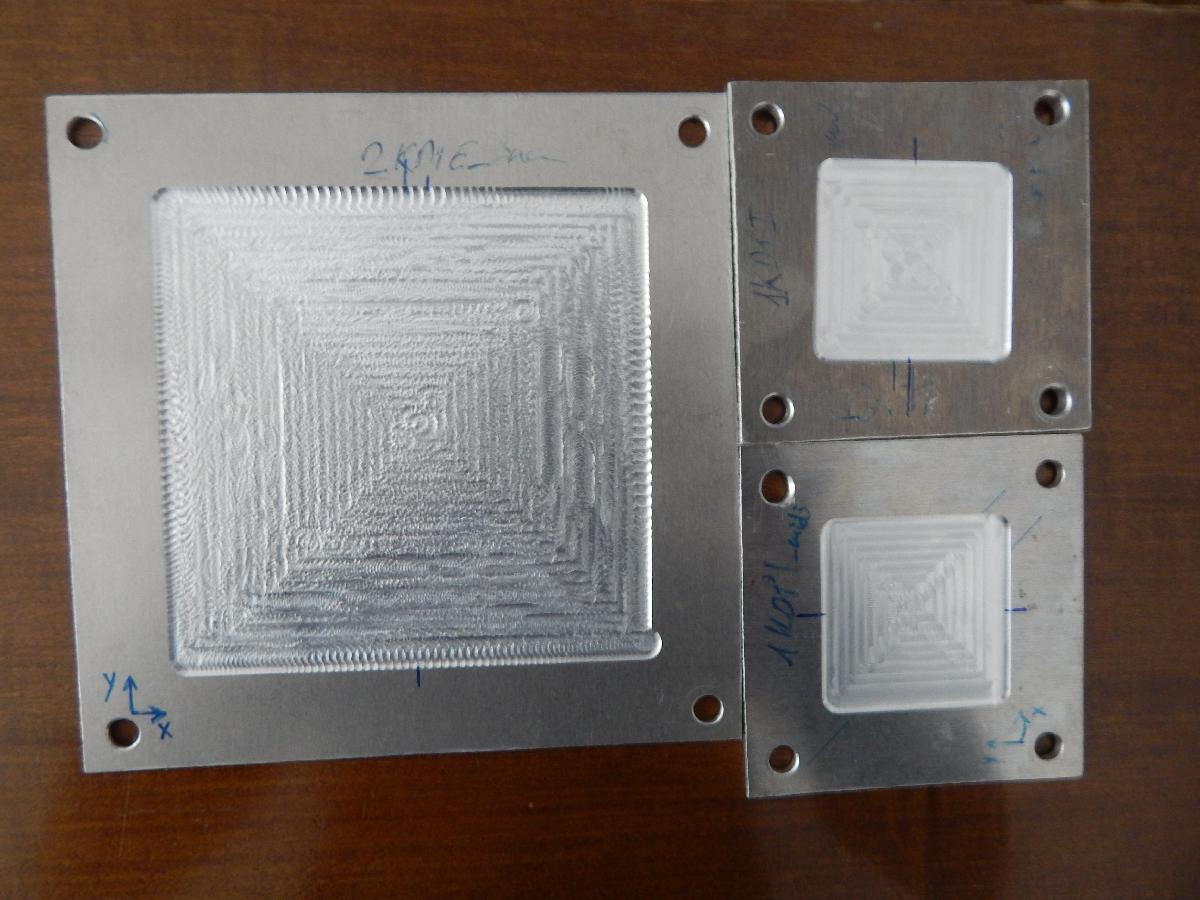    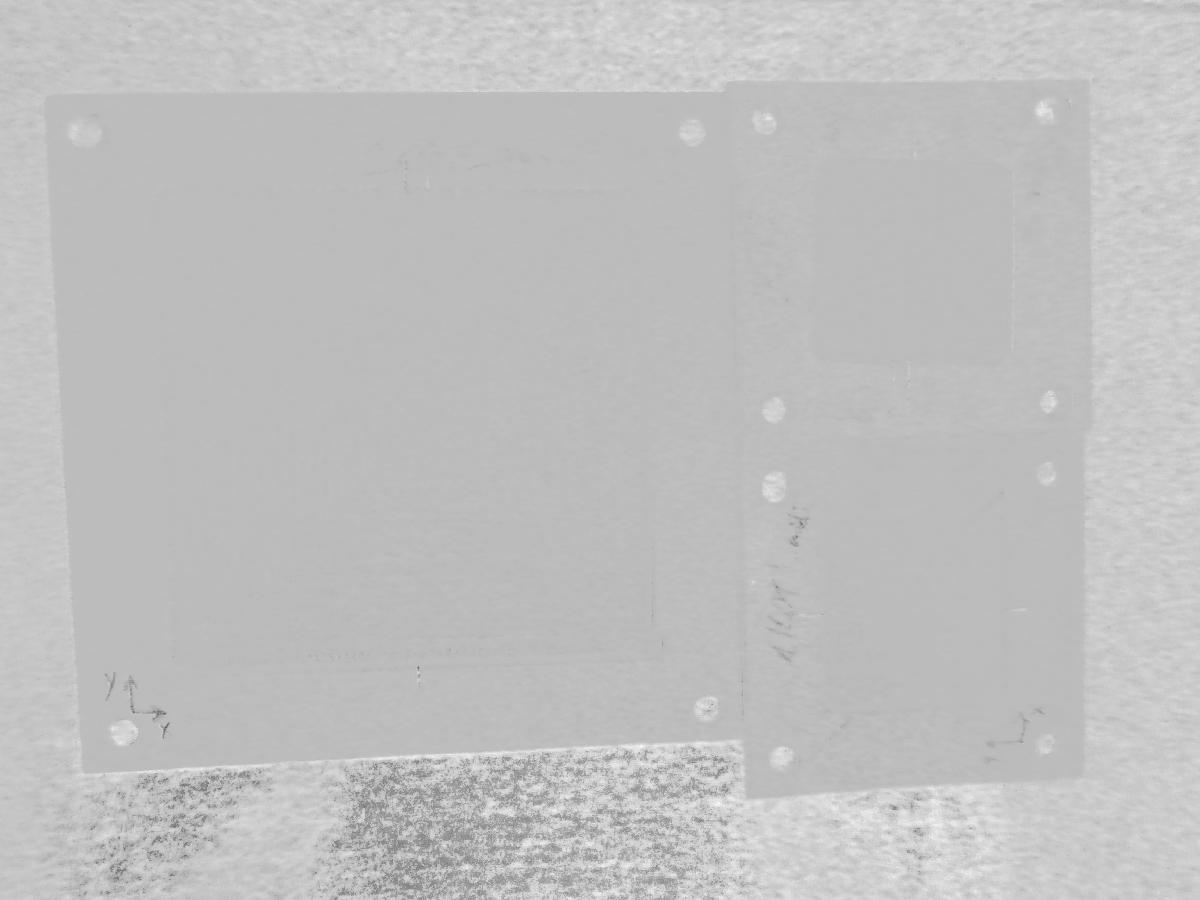

## Referencias

- Kim, T., Tai, Y. W., & Yoon, S. E. "PCA based Computation of Illumination-Invariant Space for Road Detection," *IEEE Winter Conference on Applications of Computer Vision*, pp. 632-640, 2017.